# Fitting the normal form dynamics 

In this example, we will fit the dynamics of the Van der Pol oscillator. It obeys the ordinary differential equation


$$\dot{x}=y \\
\dot{y}=\mu (1-x^{2})y-x\end{array}}\right.$$


## Generating synthetic data

We generate some data with $\mu <0$.

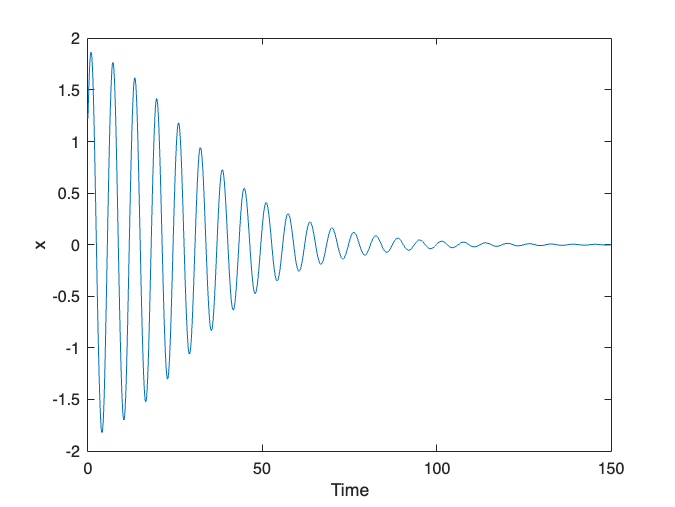

clear all;
close all;
mu = -0.1;
rhs_fun = @(t, x) [x(2); mu * (1 - x(1).^2 ) * x(2) - x(1)];
rng(0);
ic = 1.5*rand(2,1);
t_eval = linspace(0, 150, 5000);
[t,sol] = ode45(rhs_fun, t_eval, ic);
plot(t, sol(:,1), '-');
xlabel('Time');
ylabel('x');

## Setting up the variables for fitting the dynamics

We prepare a cell array that is compatible with SSMLearn. We then input the observable vectors, which coincide with the phase-space coordinates. 

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      0.000491741                       0.00371
     1           3      0.000318185             10        0.00221  
     2           4      0.000119013              1        0.00231  
     3           5      5.55922e-05              1         0.0016  
     4           6      1.72015e-05              1       0.000709  
     5           7      6.27681e-07              1        3.5e-05  
     6           8      4.99271e-07              1       2.49e-05  
     7           9      3.87824e-07              1        4.3e-05  
     8          10      3.64602e-07              1       4.41e-05  
     9          11      3.46657e-07              1       1.46e-05  
    10          12      3.36187e-07              1       1.32e-05  
    11          13

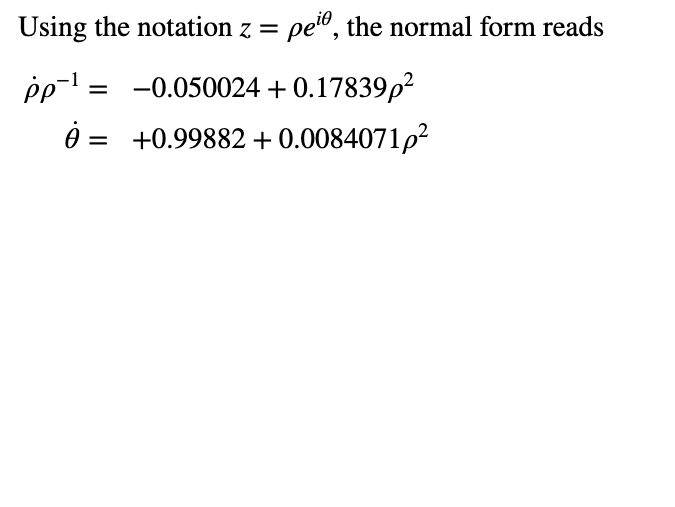

% the {j, 1} entry contains the time axis. This is now important to specify
% and needs to be of size (1, n_data)
yData{1,1} = t';

% the observables are entered in column-wise
yData{1,2} = sol';

SSMDim = 2; % we dont perform any dimension reduction now
etaData = yData;
% the order of the SSM can be specified. The simplest nontrivial model is
% with order 3
ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaData, 'R_PolyOrd', ROMOrder, 'style', 'normalform');

The returned RDInfo object contains both the normal form transformation $\mathbf{u} = \mathbf{T}(\mathbf{w})$, its inverse $\mathbf{w} = \mathbf{T}^{-1}(\mathbf{u})$ and the reduced dynamics $\dot{\bf w}={\bf R}_0{\bf w}+\sum_{|\mathbf{k}|=2}^{n_\mathrm{model}}{\bf R}^{\mathrm{norm}}_{\mathbf{k}}{\bf w}^{\mathbf{k}}$. 

In the normal form coordinates the linear part is diagonal. This means, that $\mathbf{w}$ takes complex values. In this 2D example, we can characterize the dyamics with a single complex number $z$.

zData = transformTrajectories(RDInfo.inverseTransformation.map, etaData);
zRec = integrateFlows(RDInfo.conjugateDynamics.map, zData);
etaRec = transformTrajectories(RDInfo.transformation.map, zRec);


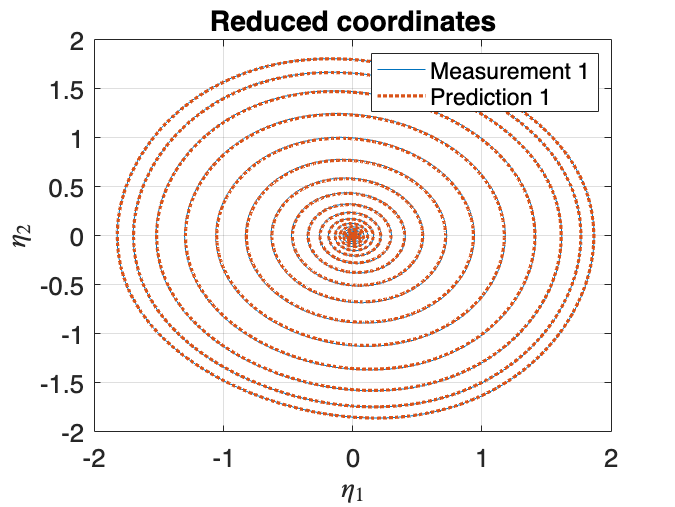

plotReducedCoordinates(etaData, etaRec)
xlabel('$\eta_1$')
ylabel('$\eta_2$')
title('Reduced coordinates')

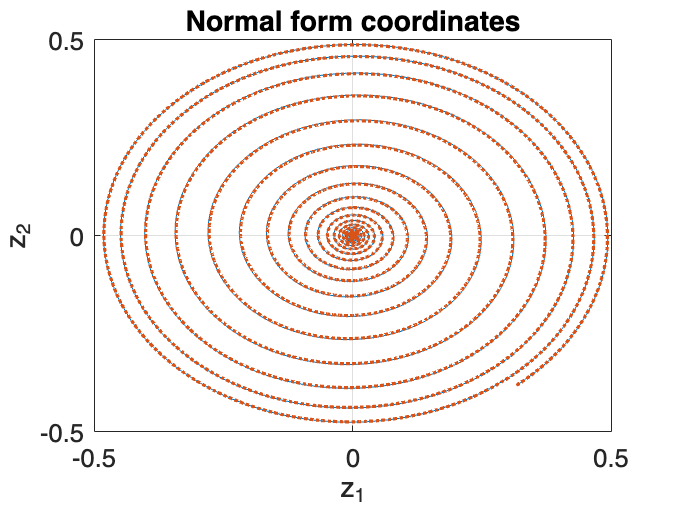

customFigure;
plot(real(zData{1,2}(1,:)), imag(zData{1,2}(1,:)),'-');
plot(real(zRec{1,2}(1,:)), imag(zRec{1,2}(1,:)), ':','LineWidth', 2);
title('Normal form coordinates')
xlabel('z_1')
ylabel('z_2')